%% Runmotorsim.m
% This script runs a simulation of a motor and plots the results
%
% required file: motorsim.slx
%
% Define motor parameters
K=1.36; % DC gain [rad/Vs]
sigma=14.1; % time constant reciprocal [1/s]

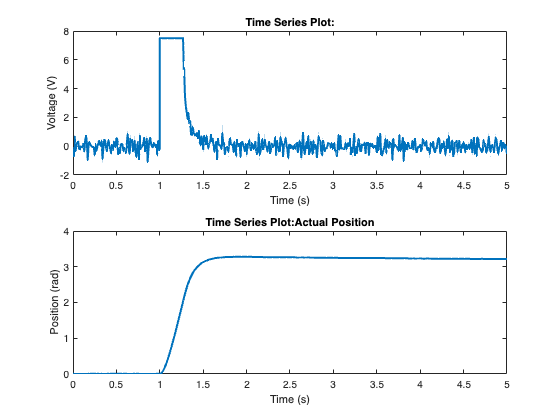

Kp = 3.2;
KI = 2;
KpI = 10;

% Run a Simulation
%
% open the block diagram so it appears in the documentation when published.
% Make sure the block diagram is closed before running the publish function
%
open_system('motorsim')
%
% run the simulation
%

out=sim('motorsim');

figure
subplot(2,1,1)
plot(out.Voltage,'linewidth',2)
xlabel('Time (s)')
ylabel('Voltage (V)')
subplot(2,1,2)
plot(out.Position,'linewidth',2)
xlabel('Time (s)')
ylabel('Position (rad)')